# **Lubrication Project**

## Setup

Code initiation

clc
clear
close all

set(0,'DefaultFigureWindowStyle','docked')

## Problem Statement

Consider an extrusion process where a fluid of high viscosity is squeezed between a flat solid surface and a roller of radius 𝑎 as shown in the figure. The roller is rotating at an angular velocity $\omega$, reducing the thickness of the fluid layer from $h_1
$ to $h_2

$ with a minimum gap of $\varepsilon$ between the roller and the flat boundary.

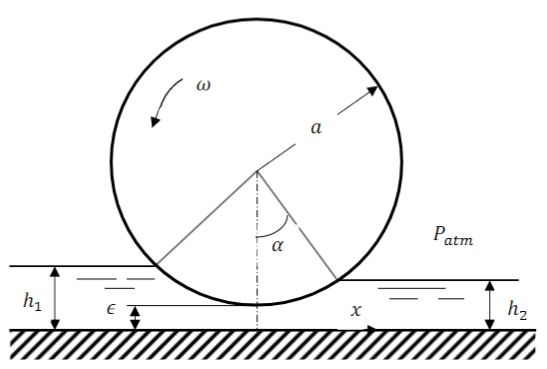

Assume a profile for the liquid layer between the roller and the flat surface in the form:

## 
$$h(x) = \varepsilon + a(1-\cos(\alpha))$$


and assume 𝛼 is small.

## a. Use the lubrication approximation to determine the pressure distribution in the liquid film and show it graphically.

syms mu dpdx h y V alpha h1 h2 a Q x y e w c1 c2 u p3
% h = e + a*(1 - (x/a))
alpha = x/a

$$alpha = \frac{x}{a}$$

% c1 = ( a*w - ( 1/(2*mu) * dpdx * (e^2) ) ) / e
vel = u == ( 1/(2*mu) * dpdx * (y^2) ) + (c1 * y) + c2

$$vel = u=c_{2}+c_{1}\,y+\frac{\mathrm{dpdx}\,y^{2}}{2\,\mu }$$

#### *Boundary Conditions*

- 
$$u(x,0) = 0$$


- 
$$u(0,\epsilon) = V = a*\omega$$


From B.C. 1:

bc1 = isolate(subs(vel,{u, y}, {0, 0}), c2)

$$bc1 = c_{2}=0$$

Thus, $c_2 = 0$

From B.C. 2:

bc2 = rhs(isolate(subs(vel,{u, y, c2}, {a*w, h, 0}), c1))

$$bc2 = \frac{a\,w-\frac{\mathrm{dpdx}\,h^{2}}{2\,\mu }}{h}$$

Thus, $c_1 =\frac{a\,w-\frac{\mathrm{dpdx}\,e^2 }{2\,\mu }}{e}$

Our final velocity function:

vel = subs(vel, {c1, c2}, {bc2, 0})

$$vel = u=\frac{\mathrm{dpdx}\,y^{2}}{2\,\mu }+\frac{y\,\left(a\,w-\frac{\mathrm{dpdx}\,h^{2}}{2\,\mu }\right)}{h}$$

u = simplify(rhs(vel))

$$u = \frac{\mathrm{dpdx}\,y^{2}}{2\,\mu }+\frac{y\,\left(a\,w-\frac{\mathrm{dpdx}\,h^{2}}{2\,\mu }\right)}{h}$$

Find Q:

fq = Q == int(u, y, [0 h])

$$fq = Q=\frac{a\,h\,w}{2}-\frac{\mathrm{dpdx}\,h^{3}}{12\,\mu }$$

Algebraically solve for $\frac{dP}{dx}$

dpdx = rhs(simplify(isolate(fq, dpdx)))

$$dpdx = -\frac{12\,\mu \,\left(Q-\frac{a\,h\,w}{2}\right)}{h^{3}}$$


b1 = sqrt((a)^2 - (a-h1)^2)

$$b1 = \sqrt{a^{2}-{\left(a-h_{1}\right)}^{2}}$$

b2 = sqrt((a)^2 - (a-h2)^2)

$$b2 = \sqrt{a^{2}-{\left(a-h_{2}\right)}^{2}}$$

dpdx_new = int(subs(dpdx, h, e + a - x), x) 

$$dpdx\_new = -\frac{6\,\mu \,\left(Q-a\,w\,\left(a+e-x\right)\right)}{{\left(a+e-x\right)}^{2}}$$

p1 = subs(dpdx_new, x, b2)

$$p1 = -\frac{6\,\mu \,\left(Q-a\,w\,\left(a+e-\sqrt{a^{2}-{\left(a-h_{2}\right)}^{2}}\right)\right)}{{\left(a+e-\sqrt{a^{2}-{\left(a-h_{2}\right)}^{2}}\right)}^{2}}$$

p2 = subs(dpdx_new, x, -b1)

$$p2 = -\frac{6\,\mu \,\left(Q-a\,w\,\left(a+e+\sqrt{a^{2}-{\left(a-h_{1}\right)}^{2}}\right)\right)}{{\left(a+e+\sqrt{a^{2}-{\left(a-h_{1}\right)}^{2}}\right)}^{2}}$$

p = 0 == p1 - p2

$$p = \begin{array}{l} 0=\frac{6\,\mu \,\left(Q-a\,w\,\sigma_{2}\right)}{{\sigma_{2}}^{2}}-\frac{6\,\mu \,\left(Q-a\,w\,\sigma_{1}\right)}{{\sigma_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=a+e-\sqrt{a^{2}-{\left(a-h_{2}\right)}^{2}}\\ \sigma_{2}=a+e+\sqrt{a^{2}-{\left(a-h_{1}\right)}^{2}} \end{array}$$

subs(isolate(p, Q), {w, mu, a, e, h1, h2}, {0.09817477, 0.01, 1, 0.001, 0.02, 0.0002})

$$ans = Q=\frac{\frac{10611356582140419}{1801439850948198400\,\left(\frac{\sqrt{99}}{50}+\frac{1001}{1000}\right)}+\frac{10611356582140419}{1801439850948198400\,\left(\frac{\sqrt{9999}}{5000}-\frac{1001}{1000}\right)}}{\frac{3}{50\,{\left(\frac{\sqrt{99}}{50}+\frac{1001}{1000}\right)}^{2}}-\frac{3}{50\,{\left(\frac{\sqrt{9999}}{5000}-\frac{1001}{1000}\right)}^{2}}}$$

Q_pred = rhs(vpa(subs(isolate(p, Q), {w, mu, a, e, h1, h2}, {0.09817477, 0.01, 1, 0.001, 0.02, 0.0002})))

$$Q\_pred = 0.052990048244679559309494467116678$$

dpdx_plot = vpa(subs(dpdx_new, {w, mu, a, e, Q}, {0.09817477, 0.01, 1, 0.001, Q_pred}))

$$dpdx\_plot = -\frac{0.06\,\left(0.098174769999999994540829106881574\,x-0.045282896525320435225875468871777\right)}{{\left(x-1.001\right)}^{2}}$$

x_vals = -1 : 0.05 : 1

x_vals =    -1.0000   -0.9500   -0.9000   -0.8500   -0.8000   -0.7500   -0.7000   -0.6500   -0.6000   -0.5500   -0.5000   -0.4500   -0.4000   -0.3500   -0.3000   -0.2500   -0.2000   -0.1500   -0.1000   -0.0500         0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


dpdx_plot1 = subs(dpdx_plot, x, x_vals)

$$dpdx\_plot1 = \left(\begin{array}{ccccccccccccccccccccccccccccccccccccccccc} 0.0021497147457054146055413758750812 & 0.0021839358705294649203748599331905 & 0.0022188303593693249348144238999081 & 0.0022543590003970070159733222257734 & 0.0022904675240632944223140655285968 & 0.0023270828814208559840293065599057 & 0.0023641085807045846338849508316797 & 0.0024014188201997232742393385653201 & 0.0024388510739185986261016502334555 & 0.0024761966766389047615959124806643 & 0.0025131888052953487147930255418235 & 0.0025494870485571280559641199078509 & 0.0025846574724178487694536668248408 & 0.0026181466926213748507205175631723 & 0.0026492479039769124650685259291321 & 0.0026770560156314443451888942790006 & 0.0027004078834659890335922378138157 & 0.0027178019351730758539735326998099 & 0.0027272889657071938406233807541786 & 0.0027263220850960899883080093653286 & 0.0027115479840032356390388114705541 & 0.0026785126083664504240154984477703 & 0.00262123989933398227682344994773 & 0.0025316187930135779468477206885554 & 0.0023984946275321051230633662505634 & 0.0022062943886965203881555024354266 & 0.0019328978400923608454553495178852 & 0.0015462531271026406926720722409659 & 0.00099883253789227118577365391333043 & 0.000218230511491155368230480948693 & -0.00090943585276860937873691767817889 & -0.0025702608073744657415392864085491 & -0.0050827913289144575588293587442244 & -0.0090246202423744423628039304557167 & -0.015522638254332442877697755617703 & -0.02699783905780501326621453115608 & -0.049390242035612327031689042301154 & -0.10043153714665030516335934032076 & -0.253353964168294636962282485962 & -1.1068773927261720781525301652991 & -3173.5124084807735588972182805878 \end{array}\right)$$

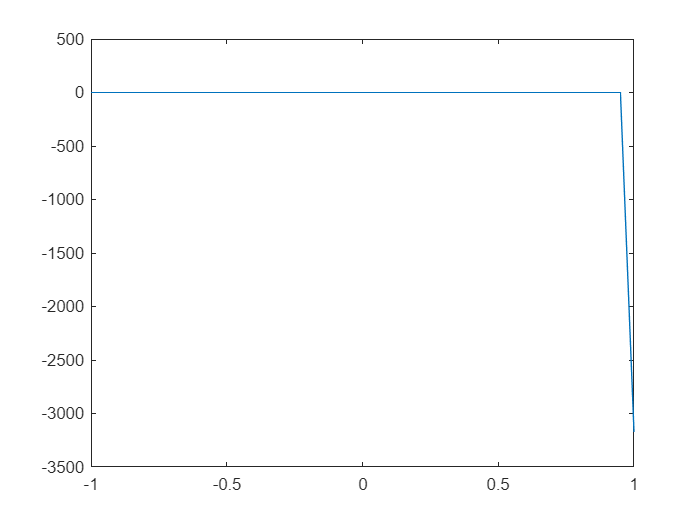

plot(x_vals, dpdx_plot1)
hold off

alph = -10 : 0.5 : 10

alph =   -10.0000   -9.5000   -9.0000   -8.5000   -8.0000   -7.5000   -7.0000   -6.5000   -6.0000   -5.5000   -5.0000   -4.5000   -4.0000   -3.5000   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


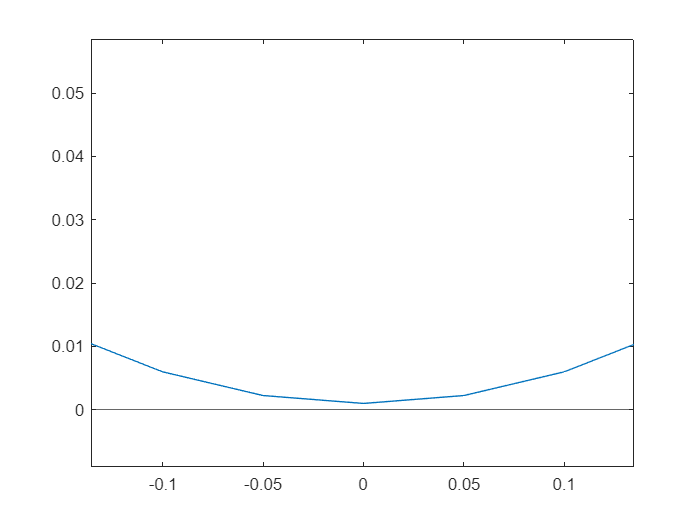

plot(x_vals, 0.001 + (1 - cos(x_vals)))
hold on
yline(0)
hold off

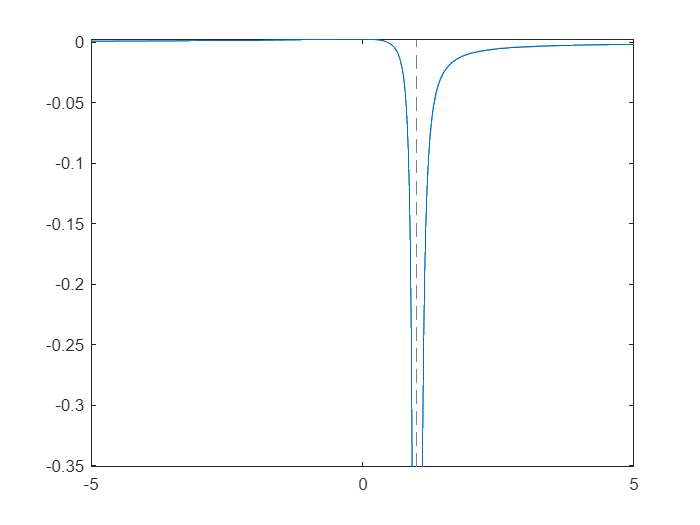

fplot(dpdx_plot)


% fp = dpdx == subs(dpdx, h, e + a - x, [-b1 b2])


% Qnew = int(rhs(isolate(fp, Q)), x)
% dpdx = simplify(subs(dpdx, Q, Qnew))

## b. Determine the maximum angular velocity which can be used to avoid cavitation.

## c. Calculate the lubrication thickness and the maximum angular velocity for the following conditions*:

#### $a = 1m$, $h_1 = 20mm$, $h_2 = 2mm$, $\varepsilon = 1mm$, $\mu = 10^4 \times \mu_{water}$